clear; close all; clc

%Import data:
didymo = importdata('didymo.obj');
dimorphus = importdata('dimorphos.obj');

%Extract index information for both verticies and faces for both
didymo_v_indices = find(strcmp(didymo.textdata, 'v'));
didymo_f_indices = find(strcmp(didymo.textdata, 'f'));

dimorphus_v_indices = find(strcmp(dimorphus.textdata, 'v'));
dimorphus_f_indices = find(strcmp(dimorphus.textdata, 'f'));

%Extract coordinatates, face and distance information for a coloursheme
didymo_coords = didymo.data(didymo_v_indices, :).*1000; %Convert to meters 
didymo_faces = didymo.data(didymo_f_indices,:);
didymo_distances = vecnorm(didymo_coords, 2, 2);

dimorphus_coords = dimorphus.data(dimorphus_v_indices, :).*1000; %Convert to meters 
dimorphus_faces = dimorphus.data(dimorphus_f_indices,:);
dimorphus_distances = vecnorm(dimorphus_coords, 2, 2);

## Calculate the orbital path:

%% Define all inputs:

m0 = 528e9; %Kg Didymo
m1 = 4.8e9; %kg Dimorphos
G=6.67e-11; %gravitational constant


%% innitial variables and calculations

mu = G*(m0+m1); %gravitational parameter
r0 = [1200, 0, 0]; %Initial location of Dimporhos
v0 = [0, -0.177, -0.0017]; %Initial velocity m/s

%% Work out the orbit
pos = orbital_equation(m0,m1,G,mu,r0,v0);

dimorphus_coords(:,1) = dimorphus_coords(:,1)+norm(r0);%Nudge dimorphus over that far as thats the seperation between the two
%Probably surface to surface however so this isnt accurate.

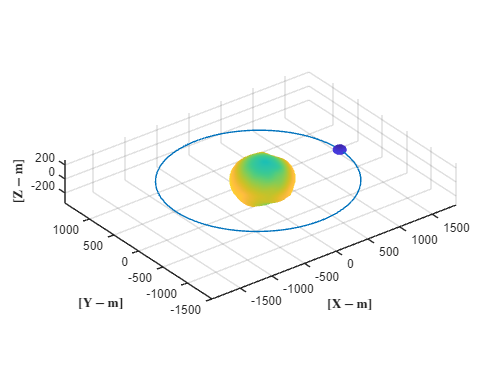

figure('color', 'w')
patch('Vertices', didymo_coords,'Faces', didymo_faces,'FaceVertexCData',didymo_distances,'FaceColor','interp','EdgeColor', 'none');
patch('Vertices', dimorphus_coords,'Faces', dimorphus_faces,'FaceVertexCData',dimorphus_distances,'FaceColor','interp','EdgeColor', 'none');

hold on;
plot3(pos(:,1), pos(:,2),pos(:,3))
scatter3(pos(1,1), pos(1,2),pos(1,3))
grid on
axis equal
xlabel('$\bf{[X - m]}$','Interpreter','latex');
ylabel('$\bf{[Y - m]}$','Interpreter','latex');
zlabel('$\bf{[Z - m]}$','Interpreter','latex');
view(3)

dimorphus_coords(:,1) = dimorphus_coords(:,1)-norm(r0);%Nudge dimorphus back over 

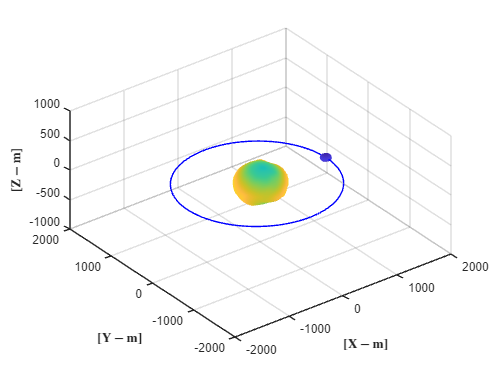

figure;
grid on
axis equal
xlabel('$\bf{[X - m]}$','Interpreter','latex');
ylabel('$\bf{[Y - m]}$','Interpreter','latex');
zlabel('$\bf{[Z - m]}$','Interpreter','latex');
xlim([-2000,2000])
ylim([-2000,2000])
zlim([-1000,1000])

% Plot Didymos
patch('Vertices', didymo_coords,'Faces', didymo_faces,'FaceVertexCData',didymo_distances,'FaceColor','interp','EdgeColor', 'none');
hold on;

% Plot Dimorphos
dimorphos_patch = patch('Vertices', dimorphus_coords,'Faces', dimorphus_faces,'FaceVertexCData',dimorphus_distances,'FaceColor','interp','EdgeColor', 'none');

% Plot the orbit of Didymos
orbit_handle = plot3(pos(:,1), pos(:,2),pos(:,3), 'b');

% Update and display the plot
view(3)

% Plot Dimorphos at each time step
for step = 1:length(pos)
    % Update Dimorphos position
    set(dimorphos_patch, 'Vertices', dimorphus_coords + pos(step,:));
    
    % Update orbit of Didymos
    set(orbit_handle, 'XData', pos(1:step,1), 'YData', pos(1:step,2), 'ZData', pos(1:step,3));
    
    % Update and display the plot
    drawnow;
end

[x,y,z] = sphere(100);
iv = 6.1e3; % velocity of Hera in km/s
tp = 2 * pi * sqrt(norm(r0)^3 / mu); % Time period of orbit
distance = iv * tp; % Distance travelled by Hera assuming constant velocity
dy = linspace(-distance, pos(1,2), length(pos)); % For the sake of simplicity only varying y 
hera_pos = pos;
hera_pos(:,2) = dy;

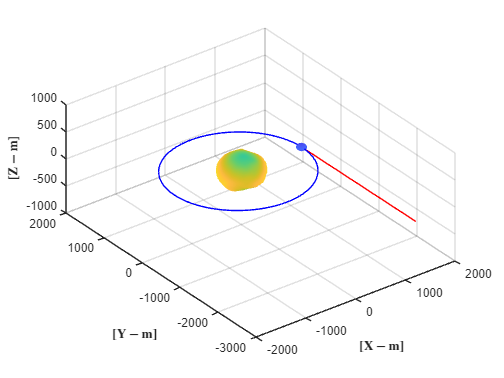

figure;
grid on
axis equal
xlabel('$\bf{[X - m]}$','Interpreter','latex');
ylabel('$\bf{[Y - m]}$','Interpreter','latex');
zlabel('$\bf{[Z - m]}$','Interpreter','latex');
xlim([-2000,2000])
ylim([-3000,2000])
zlim([-1000,1000])

% Plot Didymos
patch('Vertices', didymo_coords,'Faces', didymo_faces,'FaceVertexCData',didymo_distances,'FaceColor','interp','EdgeColor', 'none');
hold on;

% Plot Dimorphos
dimorphos_patch = patch('Vertices', dimorphus_coords,'Faces', dimorphus_faces,'FaceVertexCData',dimorphus_distances,'FaceColor','interp','EdgeColor', 'none');

% Plot the orbit of Didymos
orbit_handle = plot3(pos(:,1), pos(:,2),pos(:,3), 'b');

% Plot Hera object
hera = surf(x, y, z, 'EdgeColor', 'none');

% Plot the orbit of Hera
hera_orbit_handle = plot3(hera_pos(:,1), hera_pos(:,2), hera_pos(:,3), 'r');

% Update and display the plot
view(3)

% Plot Dimorphos at each time step
for step = 1:length(pos)
    % Update Dimorphos position
    set(dimorphos_patch, 'Vertices', dimorphus_coords + pos(step,:));
    
    % Update orbit of Didymos
    set(orbit_handle, 'XData', pos(1:step,1), 'YData', pos(1:step,2), 'ZData', pos(1:step,3));
    
    % Update position of Hera
    set(hera, 'XData', x + hera_pos(step,1), 'YData', y + hera_pos(step,2), 'ZData', z + hera_pos(step,3));
    
    % Update orbit of Hera
    set(hera_orbit_handle, 'XData', hera_pos(1:step,1), 'YData', hera_pos(1:step,2), 'ZData', hera_pos(1:step,3));
    
    % Update and display the plot
    drawnow;
end

## After impact calculations:

mass_dart = 580; % mass in Kg at impact of DART
p0 = m1*v0; %Momentum of dimorphos before 
p1 = mass_dart*[0,iv,0]; %Momentum of DART before 
pTOT = p0+p1; %Total momentum of the final system assuming perfect energy transfer and no ejected mass etc 
v1  = pTOT/(mass_dart+m1); %New total sytem velocity


%Do some more mafs
pos2 = orbital_equation(m0,m1+mass_dart,G,mu,r0,v1);

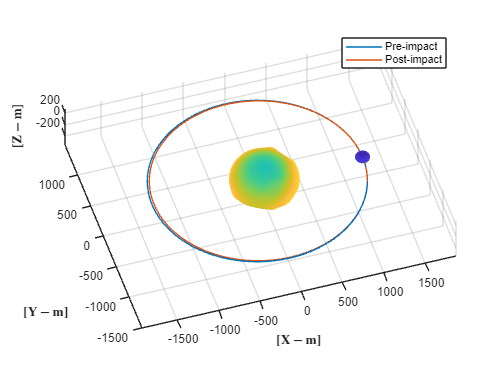

%Plot the data:

figure('color', 'w')
patch('Vertices', didymo_coords,'Faces', didymo_faces,'FaceVertexCData',didymo_distances,'FaceColor','interp','EdgeColor', 'none');
patch('Vertices', dimorphus_coords+[norm(r0),0,0],'Faces', dimorphus_faces,'FaceVertexCData',dimorphus_distances,'FaceColor','interp','EdgeColor', 'none');

hold on;
% Plot trajectories
plot1 = plot3(pos(:,1), pos(:,2),pos(:,3), 'DisplayName', 'Pre-impact');
plot2 = plot3(pos2(:,1), pos2(:,2),pos2(:,3), 'DisplayName', 'Post-impact');

grid on
axis equal
xlabel('$\bf{[X - m]}$','Interpreter','latex');
ylabel('$\bf{[Y - m]}$','Interpreter','latex');
zlabel('$\bf{[Z - m]}$','Interpreter','latex');
legend([plot1 plot2]);
view(3)